# Adaptive Machine Learning for Dynamic Radiolocation

## Simulation Environment and Dataset Configuration

% Simulation environment parameters
grid_size = 100;           % Size of grid (100m x 100m)
sigma_noise = 2;           % Noise variance level
base_stations = [25, 25;   % Base station location 1
                 25, 75;   % Base station location 2
                 75, 25;   % Base station location 3
                 75, 75];  % Base station location 4

% Set size parameters
N_train = 8000;
N_valid = 1000;
N_eval  = 10000;

% Location Measurements (2xN)
Y_train = grid_size * rand( N_train , 2); % Training Data Set
Y_valid = grid_size * rand( N_valid , 2); % Validation Data Set
Y_eval = grid_size  * rand( N_eval  , 2); % Evaluation Data Set

% RSS Measurements (4xN)
X_train = zeros( N_train , 4); % Training Data Set
X_valid = zeros( N_valid , 4); % Validation Data Set
X_eval  = zeros( N_eval  , 4); % Evaluation Data Set

% Path loss model parameters
L0 = -30;   % RSS at reference distance of 0m (perfect signal connection), in dBm
alpha = 2; % Path loss exponent
f = 2.4e9; % Frequency in Hz (2.4 GHz for WLAN/WiFi)
c = 3e8;   % Speed of light in m/s

for ii = 1 : 4
    
    % Compute Euclidean distance to the base station
    distance_to_bs_train = sqrt( sum( abs( base_stations( ii , :) - Y_train ).^2 , 2 ) );
    distance_to_bs_valid = sqrt( sum( abs( base_stations( ii , :) - Y_valid ).^2 , 2 ) );
    distance_to_bs_eval = sqrt( sum( abs( base_stations( ii , :) - Y_eval ).^2 , 2 ) );

    % Apply log-distance path loss model (gaussian noise with variance = sigma_noise^2)
    X_train(:, ii) = L0 - 10 * alpha * log10(4 * pi * distance_to_bs_train * f / c) + (sigma_noise * randn( N_train , 1 ) );
    X_valid(:, ii) = L0 - 10 * alpha * log10(4 * pi * distance_to_bs_valid * f / c) + (sigma_noise * randn( N_valid , 1 ) );
    X_eval(:, ii) = L0 - 10 * alpha * log10(4 * pi * distance_to_bs_eval * f / c) + (sigma_noise * randn( N_eval  , 1 ) );

end

## Parzen Window Estimator Method - Validation

% Define range of kernel widths to test
h_vector = 0.1 : 0.1 : 4;

% Initialize vectors to store cross-validation MSE values for each kernel width
MSE_loc_valid = zeros(size(h_vector));
MSE_rss_valid = zeros(size(h_vector));

% Perform Leave-One-Out Cross Validation for each kernel width
for hh = 1 : length(h_vector)
    
    % Test current kernel width
    h_value = h_vector(hh);

    % Estimate the weights using Gaussian kernel based on RSS similarity
    weights_loc_valid = gaussian_kernel(X_valid, X_train, h_value);
    
    % NOTE: Y data sets (locations) passed in as arguments for calculating weights to be used in rss estimation algorithm
    weights_rss_valid = gaussian_kernel(Y_valid, Y_train, h_value);

    % Compute estimated locations and RSS
    Y_loc_est = zeros( N_valid , 2); % Estimated locations
    X_rss_est = zeros( N_valid , 4); % Estimated RSS for each base station
    
    for nn = 1 : N_valid
        % Estimate the location using weighted sum of training locations
        Y_loc_est(nn, :) = sum(weights_loc_valid(nn, :) .* Y_train.', 2);
        
        % Estimate the RSS for all four base stations
        for ii = 1 : 4
            % Compute weighted sum of RSS values for each base station
            X_rss_est(nn, ii) = sum(weights_rss_valid(nn, :) .* X_train(:, ii).');
        end
    end

    % assert(size(Y_loc_est, 2) == 2, 'Y_loc_est must have 2 columns');

    % assert(size(X_rss_est, 2) == 4, 'X_rss_est must have 4 columns');

    % Compute cross-validation MSE for locations
    MSE_loc_valid(hh) = mean( sum( abs( Y_loc_est - Y_valid ).^2, 2 ) );

    % Compute cross-validation MSE for RSS
    MSE_rss_valid(hh) = mean( sum( abs( X_rss_est - X_valid ).^2, 2 ) );
end

% Find the kernel width which gave the best MSE performance for location
[~, h_best_loc_idx] = min(MSE_loc_valid);
h_x = h_vector(h_best_loc_idx);

% Find the kernel width which gave the best MSE performance for RSS
[~, h_best_rss_idx] = min(MSE_rss_valid);
h_y = h_vector(h_best_rss_idx);

% Display optimal kernel widths
fprintf('Optimal kernel width for location (hx): %.2f\n', h_x);

Optimal kernel width for location (hx): 1.60


fprintf('Optimal kernel width for RSS (hy): %.2f\n', h_y);

Optimal kernel width for RSS (hy): 2.00


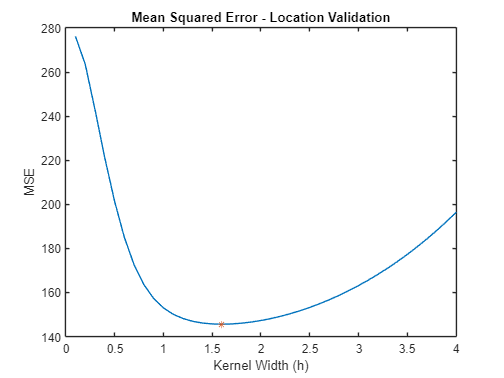

% Plot MSE for location
figure;
plot(h_vector, MSE_loc_valid, '-', h_x, MSE_loc_valid(h_best_loc_idx), '*');
title('Mean Squared Error - Location Validation');
xlabel('Kernel Width (h)');
ylabel('MSE');

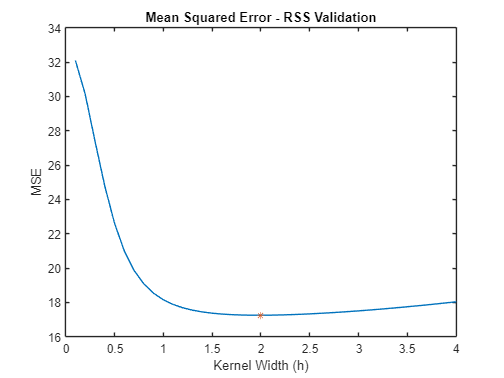

% Plot MSE for RSS
figure;
plot(h_vector, MSE_rss_valid, '-', h_y, MSE_rss_valid(h_best_rss_idx), '*');
title('Mean Squared Error - RSS Validation');
xlabel('Kernel Width (h)');
ylabel('MSE');

## Parzen Window Estimator Method - Evaluation

% Estimate weights using Gaussian kernel
weights_loc_eval = gaussian_kernel( X_eval, X_train, h_x ); % RSS kernel weights
weights_rss_eval = gaussian_kernel( Y_eval, Y_train, h_y ); % Location kernel weights

% Initialize variance matrix
variance_matrices = zeros( 2 , 2 , N_eval ); % Location variance estimation

% Compute estimated locations
Y_loc_est = zeros( N_eval , 2 );
X_rss_est = zeros( N_eval , 4 );

% Variance term constants
cov_ky = (h_y^2) * eye(2); % Covariance of kernel (h_y^2 * I)

for nn = 1 : N_eval

    % Estimate the location using weighted sum of training locations
    Y_loc_est( nn , : ) = sum( weights_loc_eval( nn , : ) .* Y_train.' , 2 );

    % Initialize variance matrix
    expectation_yyT = zeros( 2 , 2 );

    % Compute weighted expectation
    for kk = 1 : N_train

        yk = Y_train( kk, : ).'; % Training location
        kernel_weight = weights_loc_eval( nn , kk );
        expectation_yyT = expectation_yyT + kernel_weight * ( yk * yk.' + cov_ky );

    end

    % Store variance matrix
    variance_matrices( : , : , nn ) = expectation_yyT - Y_loc_est( nn , : )' * Y_loc_est( nn , : );

    % Estimate the RSS for all four base stations
    for ii = 1 : 4
        % Compute weighted sum of RSS values for each base station
        X_rss_est( nn , ii ) = sum( weights_rss_eval( nn , : ) .* X_train( : , ii ).' );
    end

end

% Compute cross-validation MSE
MSE_loc_eval = mean( sum( abs( Y_loc_est - Y_eval ).^2 , 2 ) );
fprintf('WLAN Localization - Evaluation MSE for sigma_noise = %.2f: %.4f\n', sigma_noise , MSE_loc_eval);

WLAN Localization - Evaluation MSE for sigma_noise = 2.00: 135.6275


MSE_rss_eval = mean( sum( abs( X_rss_est - X_eval ).^2 , 2 ) );
fprintf('RSS Estimation - Evaluation MSE for sigma_noise = %.2f: %.4f\n', sigma_noise , MSE_rss_eval);

RSS Estimation - Evaluation MSE for sigma_noise = 2.00: 16.6572


% Calculate the mean variance matrix
mean_variance_matrix = mean(variance_matrices, 3);
disp(mean_variance_matrix);

  101.0401    0.4872
    0.4872  104.5327



## Kalman Filter Implementation - General vs Non-General Variance Estimation

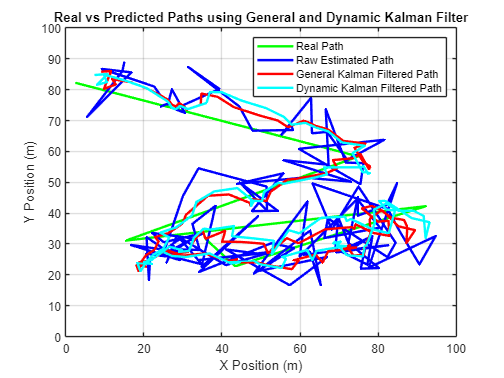

% Initialize Random Waypoint Motion Model
timeStep = 1;                               % Poll position every second
simulationTime = 120;                       % Total simulation time
true_position = grid_size * rand(1, 2);   % Initial random starting position
stopPoint = grid_size * rand(1, 2);         % Initial random stop point
speed = 1 + 2 * rand;

% State-transition matrix (location and veloctiy)
F = [1 0 timeStep 0;   
     0 1 0 timeStep;
     0 0 1 0;
     0 0 0 1];

% Observation matrix
H = [1 0 0 0;  % Only position is measured, so H matrix maps state to measurement
     0 1 0 0];

% Covariance of process noise
Q = [0.4 0 0 0; % Tuning values recommended by Dr. McGuire
     0 0.1 0 0;
     0 0 0.5 0;
     0 0 0 0.5];

% Covariance of measurement noise
R = mean_variance_matrix; % This value is the mean variance estimation calculated previously in evaluation process for PWE

% Initial State Estimate (position and velocity)
x_k = [true_position, 0, 0]'; % General Variance Estimation 
x_k_dynamic = x_k;              % Non-General Variance Estimation 

% Initial error covariance
P_k = [mean_variance_matrix, zeros(2, 2); 
       zeros(2, 2), diag([10, 10])];    % General Variance Estimation
P_k_dynamic = P_k;                      % Non-General Variance Estimation 

% Initialize matrices to store the real and predicted paths for plotting later
real_path = zeros( simulationTime , 2 );
pwe_estimated_path = zeros( simulationTime , 2 );
kalman_predicted_path = zeros( simulationTime , 2 );
dynamic_kalman_predicted_path = zeros( simulationTime , 2 );

% Main simulation loop
for t = 1 : timeStep : simulationTime

    % Save current real position
    real_path(t, :) = true_position;

    % Simulate RSS measurements
    rss_measurement = zeros(1, 4);
    for ii = 1 : 4
        distance_to_bs = norm( true_position - base_stations( ii , : ) ); % Distance to base station
        rss_measurement( ii ) = L0 - 10 * alpha * log10(4 * pi * distance_to_bs * f / c) + ( sigma_noise * randn );
    end

    % Estimate position using PWE
    weights_loc = gaussian_kernel( rss_measurement , X_train , h_x );
    pwe_estimated_position = sum( weights_loc .* Y_train.' , 2 ).'; % PWE-estimated location
    
    % Save the PWE estimated position
    pwe_estimated_path( t , : ) = pwe_estimated_position;



    % Kalman Filter Implementation - General Variance Estimation 
    % Predict the next state
    x_k_plus_1 = F * x_k;                   % Predicted state estimate
    P_k_plus_1 = F * P_k * F' + Q;          % Predicted covariance estimate

    % Measurement update (PWE-estimated location)
    z_k = pwe_estimated_position';

    % Kalman gain calculation
    S_k = H * P_k_plus_1 * H' + R;  % Innovation covariance
    K_k = P_k_plus_1 * H' / S_k;    % Kalman gain

    % Update the state estimate
    x_k = x_k_plus_1 + K_k * (z_k - H * x_k_plus_1);
    
    % Update the error covariance
    P_k = (eye(4) - K_k * H) * P_k_plus_1;
    
    % Save the predicted position
    kalman_predicted_path(t, :) = x_k( 1 : 2 );  % Predicted position from Kalman filter
    


    % Kalman Filter Implementation - Non-General Variance Estimation 
    % Predict the next state
    x_k_plus_1_dynamic = F * x_k_dynamic;             % Predicted state estimate
    P_k_plus_1_dynamic = F * P_k_dynamic * F' + Q;    % Predicted covariance estimate

    % Initialize variance matrix
    dynamic_variance_matrix = zeros( 2 , 2 );

    % Compute weighted expectation
    for kk = 1 : N_train

        yk = Y_train( kk, : ).'; % Training location
        dynamic_variance_matrix = dynamic_variance_matrix + weights_loc( kk ) * ( yk * yk.' + cov_ky );

    end

    % Store variance matrix
    R_dynamic = dynamic_variance_matrix - pwe_estimated_position' * pwe_estimated_position;

    % Kalman gain calculation with dynamic R
    S_k_dynamic = H * P_k_plus_1_dynamic * H' + R_dynamic;  % Innovation covariance
    K_k_dynamic = P_k_plus_1_dynamic * H' / S_k_dynamic;    % Kalman gain

    % Update the state estimate
    x_k_dynamic = x_k_plus_1_dynamic + K_k_dynamic * ( z_k - H * x_k_plus_1_dynamic );
    
    % Update the error covariance
    P_k_dynamic = (eye(4) - K_k_dynamic * H) * P_k_plus_1_dynamic;

    % Save the predicted position
    dynamic_kalman_predicted_path( t , : ) = x_k_dynamic( 1 : 2 );  % Predicted position from dynamic Kalman filter


    
    % If the distance to the current stop point is less than the current movement increment, 
    % jump directly to the stop point. Once there, generate a new stop point and speed, then 
    % wait for the next time step. 
    if norm(stopPoint - true_position) <= speed * timeStep
        true_position = stopPoint;         % Jump to stop point
        stopPoint = grid_size * rand(1, 2);  % Generate new stop point
        speed = 1 + 2 * rand;                % Generate new speed
    else
        % The current stop point has not been reached so continue
        % travelling towards it at the current set speed.
        direction = (stopPoint - true_position) / norm(stopPoint - true_position);
        true_position = true_position + speed * timeStep * direction;
    end
end

% Plot real and predicted paths for both implementations
figure;
plot(real_path(:, 1), real_path(:, 2), 'g-', ...
     pwe_estimated_path(:, 1), pwe_estimated_path(:, 2), 'b-', ...
     kalman_predicted_path(:, 1), kalman_predicted_path(:, 2), 'r-', ...
     dynamic_kalman_predicted_path(:, 1), dynamic_kalman_predicted_path(:, 2), 'c-', 'LineWidth', 2); 
legend('Real Path', 'Raw Estimated Path', 'General Kalman Filtered Path', 'Dynamic Kalman Filtered Path');
title('Real vs Predicted Paths using General and Dynamic Kalman Filter');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([0 grid_size 0 grid_size]);
grid on;

pwe_MSE = mean( sum( abs( real_path( : , 1:2 ) - pwe_estimated_path( : , 1 : 2 ) ).^2 , 2 ) )

pwe_MSE = 110.5346

kalman_MSE = mean( sum( abs( real_path( : , 1:2 ) - kalman_predicted_path( : , 1 : 2 ) ).^2 , 2 ) )

kalman_MSE = 49.0651

dynamic_kalman_MSE = mean( sum( abs( real_path( : , 1:2 ) - dynamic_kalman_predicted_path( : , 1 : 2 ) ).^2 , 2 ) )

dynamic_kalman_MSE = 37.5206

## Covariance of Process Noise - Tuning Parameter Optimization

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.981472e+01    0.000e+00    1.632e+00
    1      11    5.852449e+01    0.000e+00    2.747e+00    7.002e-01
    2      17    5.780001e+01    0.000e+00    1.786e+00    2.059e-01
    3      23    5.752228e+01    0.000e+00    6.044e+00    2.165e-01
    4      28    5.661607e+01    0.000e+00    7.950e+01    2.493e+00
    5      33    5.538838e+01    0.000e+00    1.284e+00    6.951e+00
    6      38    5.532883e+01    0.000e+00    7.361e+00    2.049e+00
    7      43    5.524089e+01    0.000e+00    2.697e+00    3.379e-01
    8      48    5.506316e+01    0.000e+00    5.830e+01    1.758e+00
    9      53    5.476083e+01    0.000e+00    2.106e+01    5.976e-01
   10      58    4.800899e+01    0.000e+00    4.082e+02    2.687e+00
   11      67    4.713381e+01    0.000e+00    1.147e+00    1.701e+00
   12      72    4.701797e+01    0.000e+00    1

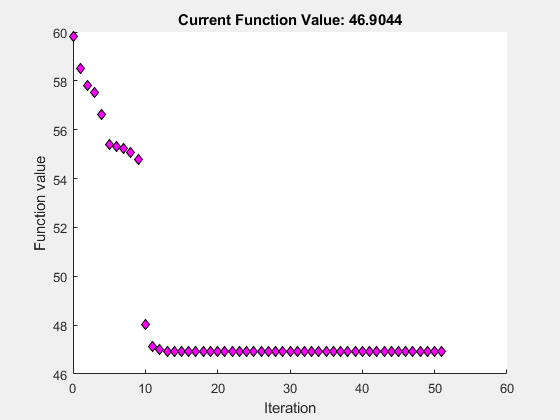


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Define the objective function
objective_func = @(q) simulate_kalman(q, mean_variance_matrix, X_train, h_x, Y_train);

% Initial guess for Q elements
q_init = [0.4, 0.1, 0.5, 0.5];

% Set optimization bounds for Q elements
lb = [0, 0, 0, 0];  % Lower bounds
ub = [10, 10, 10, 10];  % Upper bounds

% Minimize the objective function
options = optimset('Display', 'iter', 'PlotFcns', @optimplotfval);
optimized_q = fmincon(objective_func, q_init, [], [], [], [], lb, ub, [], options);

% Reshape optimized_q into matrix form
optimized_Q = diag(optimized_q)

optimized_Q =     8.0495         0         0         0
         0    9.9962         0         0
         0         0    0.0243         0
         0         0         0    0.0085


## Final Proof of Concept - Dynamic Kalman Filter vs Neural Network Performance Comparison

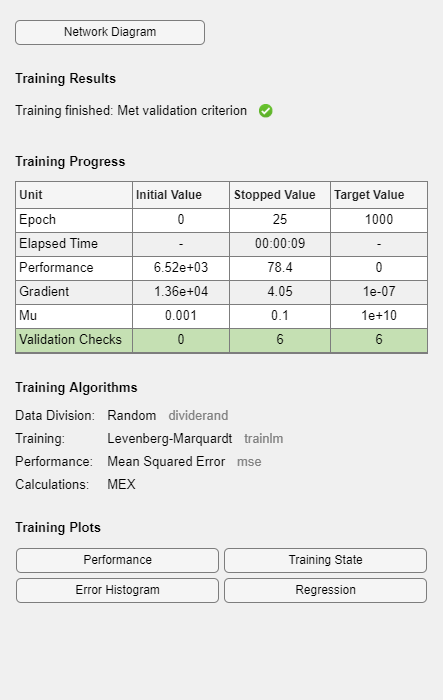

% Construct a feedforward network with one hidden layer of size 10
net = feedforwardnet(10);

% Train the network
[net, tr] = train(net, X_train', Y_train');

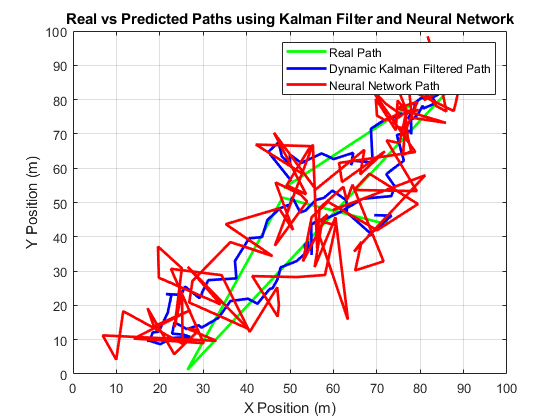

% Initialize Random Waypoint Motion Model
timeStep = 1;                               % Poll position every second
simulationTime = 120;                       % Total simulation time
true_position = grid_size * rand(1, 2);     % Initial random starting position
stopPoint = grid_size * rand(1, 2);         % Initial random stop point
speed = 1 + 2 * rand;

% State-transition matrix (location and veloctiy)
F = [1 0 timeStep 0;   
     0 1 0 timeStep;
     0 0 1 0;
     0 0 0 1];

% Observation matrix
H = [1 0 0 0;  % Only position is measured, so H matrix maps state to measurement
     0 1 0 0];

% Covariance of process noise
Q = optimized_Q;

% Initial State Estimate (position and velocity)
x_k_dynamic = [true_position, 0, 0]'; 

% Initial error covariance
P_k_dynamic = [mean_variance_matrix, zeros(2, 2); 
               zeros(2, 2), diag([10, 10])];    

% Initialize matrices to store the real and predicted paths for plotting later
real_path = zeros( simulationTime , 2 );
dynamic_kalman_predicted_path = zeros( simulationTime , 2 );
nn_predicted_path = zeros( simulationTime , 2 );

% Main simulation loop
for t = 1 : timeStep : simulationTime

    % Save current real position
    real_path(t, :) = true_position;

    % Simulate RSS measurements
    rss_measurement = zeros(1, 4);
    for ii = 1 : 4
        distance_to_bs = norm( true_position - base_stations( ii , : ) ); % Distance to base station
        rss_measurement( ii ) = L0 - 10 * alpha * log10(4 * pi * distance_to_bs * f / c) + ( sigma_noise * randn );
    end

    % Estimate position using PWE
    weights_loc = gaussian_kernel( rss_measurement , X_train , h_x );
    pwe_estimated_position = sum( weights_loc .* Y_train.' , 2 ).'; % PWE-estimated location

    % Dynamic Kalman Filter Localization
    % Predict the next state
    x_k_plus_1_dynamic = F * x_k_dynamic;             % Predicted state estimate
    P_k_plus_1_dynamic = F * P_k_dynamic * F' + Q;    % Predicted covariance estimate

    % Measurement update (PWE-estimated location)
    z_k = pwe_estimated_position';

    % Initialize variance matrix
    dynamic_variance_matrix = zeros( 2 , 2 );

    % Compute weighted expectation
    for kk = 1 : N_train

        yk = Y_train( kk, : ).'; % Training location
        dynamic_variance_matrix = dynamic_variance_matrix + weights_loc( kk ) * ( yk * yk.' + cov_ky );

    end

    % Covariance of measurement noise
    R_dynamic = dynamic_variance_matrix - pwe_estimated_position' * pwe_estimated_position;

    % Kalman gain calculation with dynamic R
    S_k_dynamic = H * P_k_plus_1_dynamic * H' + R_dynamic;  % Innovation covariance
    K_k_dynamic = P_k_plus_1_dynamic * H' / S_k_dynamic;    % Kalman gain

    % Update the state estimate
    x_k_dynamic = x_k_plus_1_dynamic + K_k_dynamic * ( z_k - H * x_k_plus_1_dynamic );
    
    % Update the error covariance
    P_k_dynamic = (eye(4) - K_k_dynamic * H) * P_k_plus_1_dynamic;

    % Save the predicted position
    dynamic_kalman_predicted_path( t , : ) = x_k_dynamic( 1 : 2 );  % Predicted position from dynamic Kalman filter



    % Neural Network Localization
    nn_predicted_position = net(rss_measurement');  % NN predicted position
    nn_predicted_path(t, :) = nn_predicted_position';  % Store NN predicted position


    
    % If the distance to the current stop point is less than the current movement increment, 
    % jump directly to the stop point. Once there, generate a new stop point and speed, then 
    % wait for the next time step. 
    if norm(stopPoint - true_position) <= speed * timeStep
        true_position = stopPoint;           % Jump to stop point
        stopPoint = grid_size * rand(1, 2);  % Generate new stop point
        speed = 1 + 2 * rand;                % Generate new speed
    else
        % The current stop point has not been reached so continue
        % travelling towards it at the current set speed.
        direction = (stopPoint - true_position) / norm(stopPoint - true_position);
        true_position = true_position + speed * timeStep * direction;
    end
end

% Plot real and predicted paths for both implementations
figure;
plot(real_path(:, 1), real_path(:, 2), 'g-', ...
     dynamic_kalman_predicted_path(:, 1), dynamic_kalman_predicted_path(:, 2), 'b-', ...
     nn_predicted_path(:, 1), nn_predicted_path(:, 2), 'r-', 'LineWidth', 2); 
legend('Real Path', 'Dynamic Kalman Filtered Path', 'Neural Network Path');
title('Real vs Predicted Paths using Kalman Filter and Neural Network');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([0 grid_size 0 grid_size]);
grid on;

dynamic_kalman_MSE = mean( sum( abs( real_path( : , 1:2 ) - dynamic_kalman_predicted_path( : , 1 : 2 ) ).^2 , 2 ) )

dynamic_kalman_MSE = 50.6617

nn_MSE = mean( sum( abs( real_path( : , 1:2 ) - nn_predicted_path( : , 1 : 2 ) ).^2 , 2 ) )

nn_MSE = 114.7496